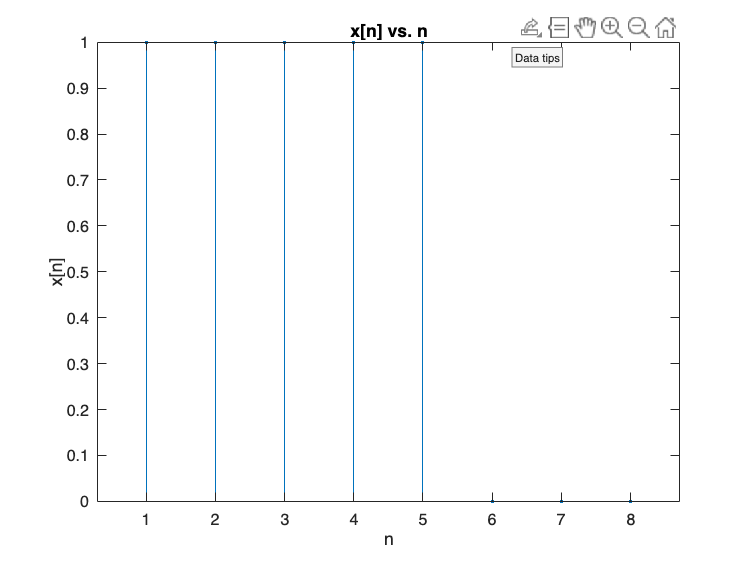

clear
n = 1:8;
x_arr = zeros(1,8);
y_arr = zeros(1,8);
x_arr(1:5) = 1;
y_arr(3:6) = 1;

stem(n, x_arr, '.');
title('x[n] vs. n', 'FontSize', 16);
xlabel('n', 'FontSize', 16);
ylabel('x[n]', 'FontSize', 16);

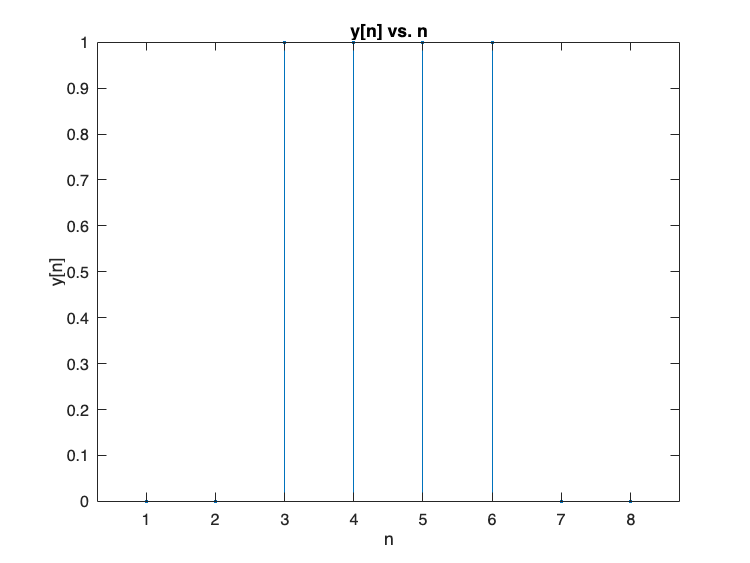


stem(n, y_arr, '.');
title('y[n] vs. n', 'FontSize', 16);
xlabel('n', 'FontSize', 16);
ylabel('y[n]', 'FontSize', 16);

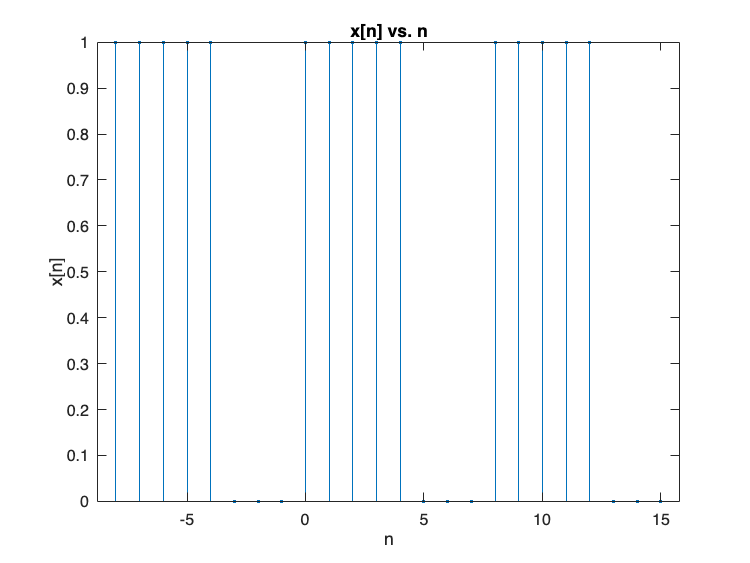

n = -8:15;
x_arr3 = zeros(1, length(n));
for i = 0:2
    x_arr3(8*i+1:8*(i+1))=x_arr;
end

stem(n, x_arr3, '.');
title('x[n] vs. n', 'FontSize', 16)
xlabel('n', 'FontSize', 16);
ylabel('x[n]', 'FontSize', 16);

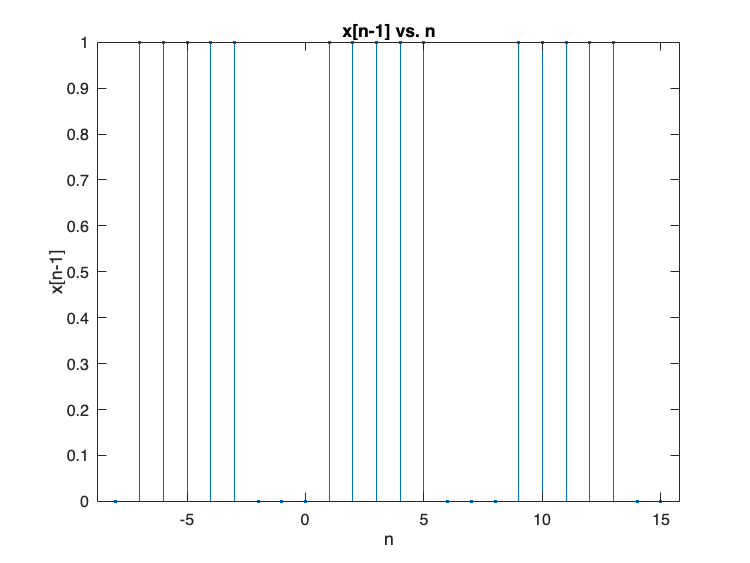

x_ext=x_arr3;
x_ext(25:48)=x_arr3;

shiftval=1;
stem(n, x_ext(9-shiftval:32-shiftval), '.');
title('x[n-1] vs. n', 'FontSize', 16);
xlabel('n', 'FontSize', 16);
ylabel('x[n-1]', 'FontSize', 16);

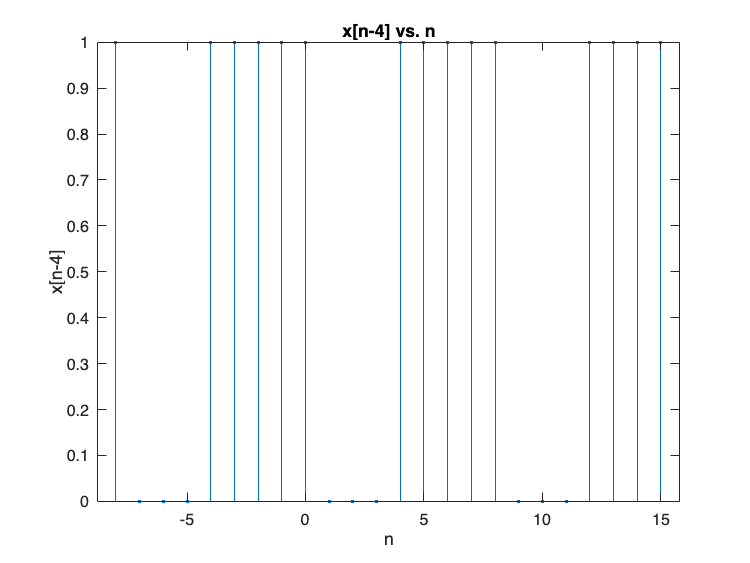


shiftval=4;
stem(n, x_ext(9-shiftval:32-shiftval), '.');
title('x[n-4] vs. n', 'FontSize', 16);
xlabel('n', 'FontSize', 16);
ylabel('x[n-4]', 'FontSize', 16);

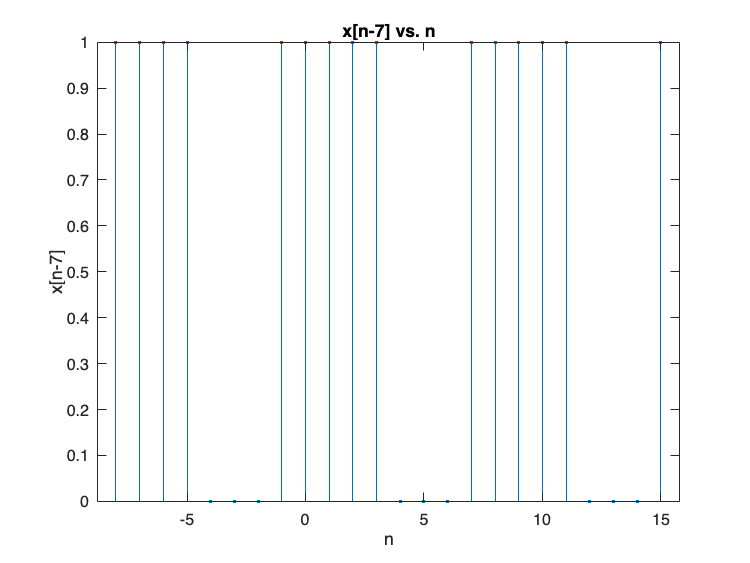


shiftval=7;
stem(n, x_ext(9-shiftval:32-shiftval), '.');
title('x[n-7] vs. n', 'FontSize', 16);
xlabel('n', 'FontSize', 16);
ylabel('x[n-7]', 'FontSize', 16);

stem(n, circshift(x_arr3, 0), '.');
title('x[n] vs. n', 'FontSize', 16);
xlabel('n', 'FontSize', 16);
ylabel('x[n]', 'FontSize', 16);


stem(n, circshift(x_arr3, 1), '.');
title('x[n-1] vs. n', 'FontSize', 16);
xlabel('n', 'FontSize', 16);
ylabel('x[n-1]', 'FontSize', 16);


stem(n, circshift(x_arr3, 4), '.');
title('x[n-4] vs. n', 'FontSize', 16);
xlabel('n', 'FontSize', 16);
ylabel('x[n-4]', 'FontSize', 16);


stem(n, circshift(x_arr3, 7), '.');
title('x[n-7] vs. n', 'FontSize', 16);
xlabel('n', 'FontSize', 16);
ylabel('x[n-7]', 'FontSize', 16);

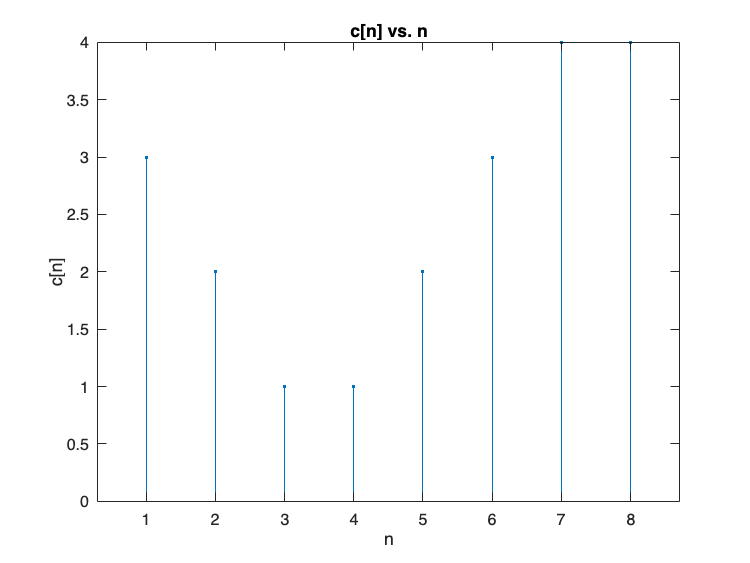

N = 8;
c_arr = zeros(1, N);
% Remember that convolution has to happen over any one period. 1:N is convenient
for idx = 1:N
    % First flip
    y_flipped = y_arr(N:-1:1);

    % Then advance using circshift
    y_shifted = circshift(y_flipped, idx-1);
    c_arr(idx) = sum(x_arr.*y_shifted);
end

stem(1:N, c_arr, '.')
title('c[n] vs. n', 'FontSize', 16);
xlabel('n', 'FontSize', 16);
ylabel('c[n]', 'FontSize', 16);

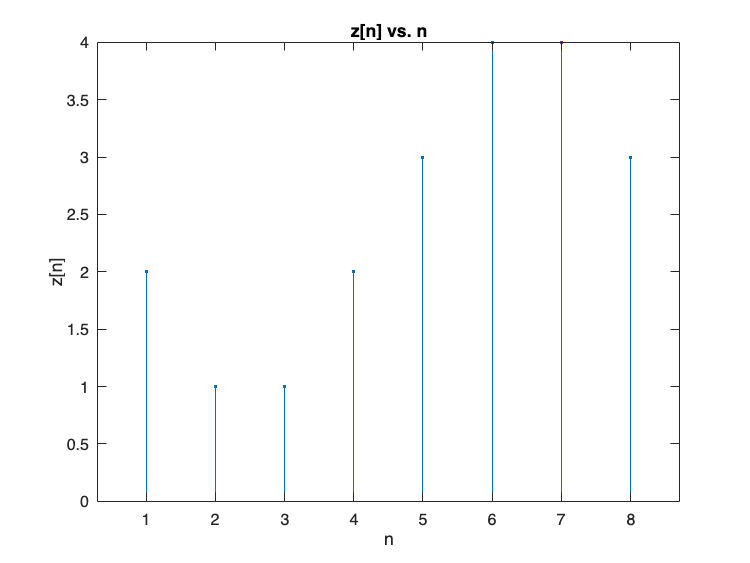

a_k = fft(x_arr);
b_k = fft(y_arr);
c_k = a_k .* b_k;
z_arr = ifft(c_k);

stem(1:N, z_arr, '.');
title('z[n] vs. n', 'FontSize', 16);
xlabel('n', 'FontSize', 16);
ylabel('z[n]', 'FontSize', 16);

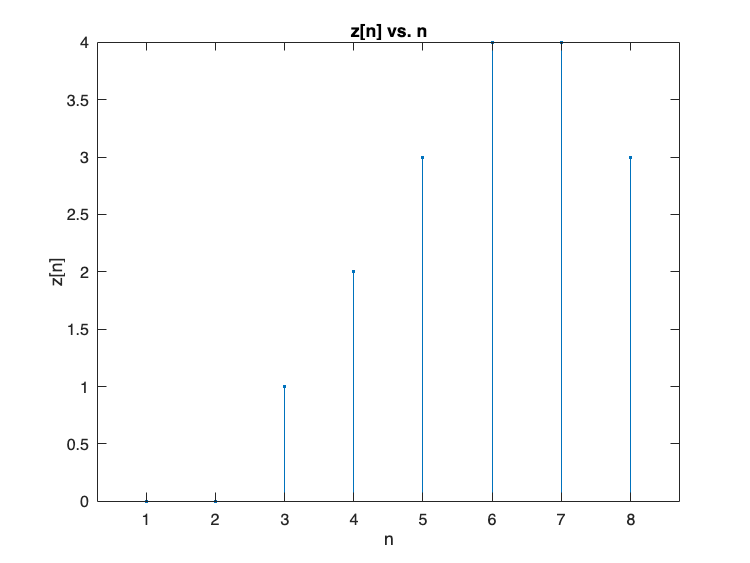

z_conv_linear = conv(x_arr, y_arr);
z_conv_linear = z_conv_linear(1:N);

stem(1:N, z_conv_linear, '.');
title('z[n] vs. n', 'FontSize', 16);
xlabel('n', 'FontSize', 16);
ylabel('z[n]', 'FontSize', 16);